Neural Net V1

Load

% Load the necessary data if not already in the workspace
load('trainingSet.mat'); % XTrain, YTrain
load('validationSet.mat'); % XTest, YTest



YTrain = ordinal(YTrain);

One Hot Encode The Y Vars

numClasses = max(YTrain);  % Determine the number of classes

% Convert categorical or ordinal YTrain to numeric indices
YIndices = grp2idx(YTrain);

YIndices = YIndices';  % Transpose if necessary
T = full(ind2vec(YIndices, numClasses));  % Convert to one-hot encoding

Train

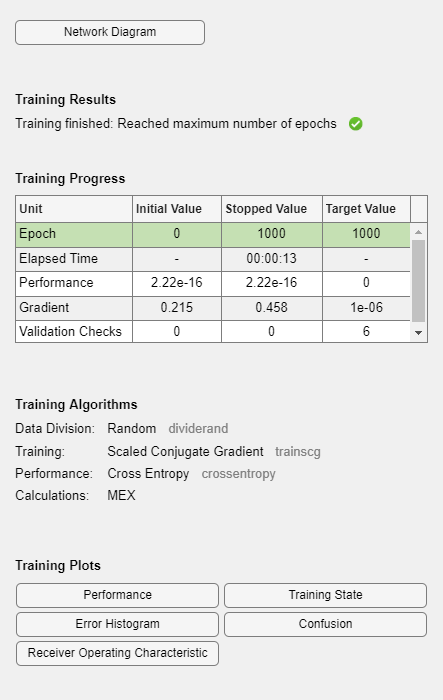


% Assuming XTrain and YTrain are your training data and labels, respectively
net = patternnet(10);  % Creates a network with 10 neurons in the hidden layer
net = train(net, XTrain', YIndices);  % Transpose might be needed based on your data format

YPred = net(XTest');  % Use the network to predict the test set
YPred = round(YPred');  % Assuming your output needs to be rounded off for class labels




Evaluate

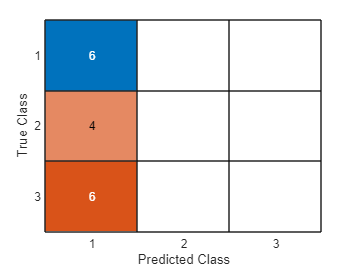

% Convert predictions to categorical if your YTest is in categorical format
YPred = categorical(YPred);

% Evaluate the classifier
confMat = confusionmat(YTest, YPred);
confusionchart(confMat);

accuracy = sum(YTest == YPred) / numel(YTest);
disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 0.375
